%% Exercise 1.4

clear
clc

% Define A matrix
A = sym([ ...
   754     0  -377; ...
     0   754   377; ...
   377  -377     0; ...
]);

% Define B matrix
B = sym([ ...
   47.1250         0; ...
         0   47.1250; ...
         0         0; ...
]);

% Define K matrix
K = sym([ ...
   -32     0     0; ...
     0   -32     0; ...
]);

% Define A_c matrix
A_c = A + B*K

$$A\_c = \left(\begin{array}{ccc} -754 & 0 & -377\\ 0 & -754 & 377\\ 377 & -377 & 0 \end{array}\right)$$

% (a) Compute the eigenvalues of A
lambda = eig(A_c)

$$lambda = \left(\begin{array}{c} -754\\ -377-377\,\mathrm{i}\\ -377+377\,\mathrm{i} \end{array}\right)$$

% (b) Compute the diagonalization of A
[Q,D] = eig(A_c)

$$Q = \left(\begin{array}{ccc} 1 & -\frac{1}{2}-\frac{1}{2}\,\mathrm{i} & -\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\\ 1 & \frac{1}{2}+\frac{1}{2}\,\mathrm{i} & \frac{1}{2}-\frac{1}{2}\,\mathrm{i}\\ 0 & 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} -754 & 0 & 0\\ 0 & -377-377\,\mathrm{i} & 0\\ 0 & 0 & -377+377\,\mathrm{i} \end{array}\right)$$

Qinv = Q^-1

$$Qinv = \left(\begin{array}{ccc} \frac{1}{2} & \frac{1}{2} & 0\\ \frac{1}{2}\,\mathrm{i} & -\frac{1}{2}\,\mathrm{i} & \frac{1}{2}+\frac{1}{2}\,\mathrm{i}\\ -\frac{1}{2}\,\mathrm{i} & \frac{1}{2}\,\mathrm{i} & \frac{1}{2}-\frac{1}{2}\,\mathrm{i} \end{array}\right)$$

% Define t
syms t

% Define x_0
x_0 = [0; 0; 1];

% (d) Compute x(t) with equilibrium initial condition
x = Q*[exp(D(1,1)*t) 0 0; 0 exp(D(2,2)*t) 0; 0 0 exp(D(3,3)*t)]*Qinv*x_0

$$x = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}+\sigma_{2}\\ \sigma_{1}-\sigma_{2}\\ {\mathrm{e}}^{t\,\left(-377-377\,\mathrm{i}\right)}\,\left(\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(-377+377\,\mathrm{i}\right)}\,\left(\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{t\,\left(-377-377\,\mathrm{i}\right)}\,\mathrm{i}}{2}\\ \sigma_{2}=\frac{{\mathrm{e}}^{t\,\left(-377+377\,\mathrm{i}\right)}\,\mathrm{i}}{2} \end{array}$$

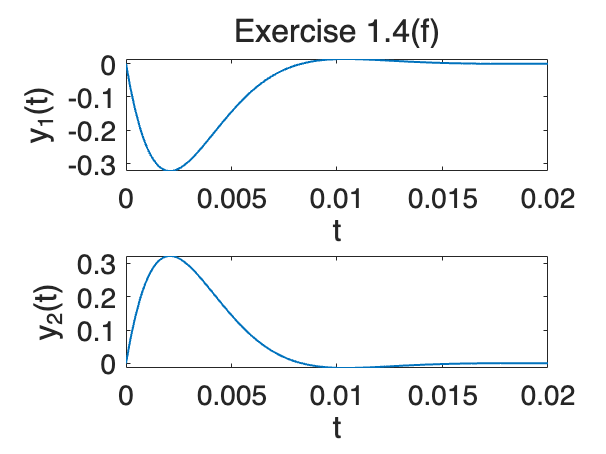

% (f) Plot output y
y1 = -exp(-377*t)*sin(377*t);
y2 = exp(-377*t)*sin(377*t);

myplot = tiledlayout(2,1);
title(myplot,"Exercise 1.4(f)","FontSize",16)
nexttile
fplot(y1,[0,0.02],"LineWidth",1)
xlabel("t")
ylabel("y_1(t)")
set(gca,"FontSize",14)
nexttile
fplot(y2,[0,0.02],"LineWidth",1)
xlabel("t")
ylabel("y_2(t)")
set(gca,"FontSize",14)